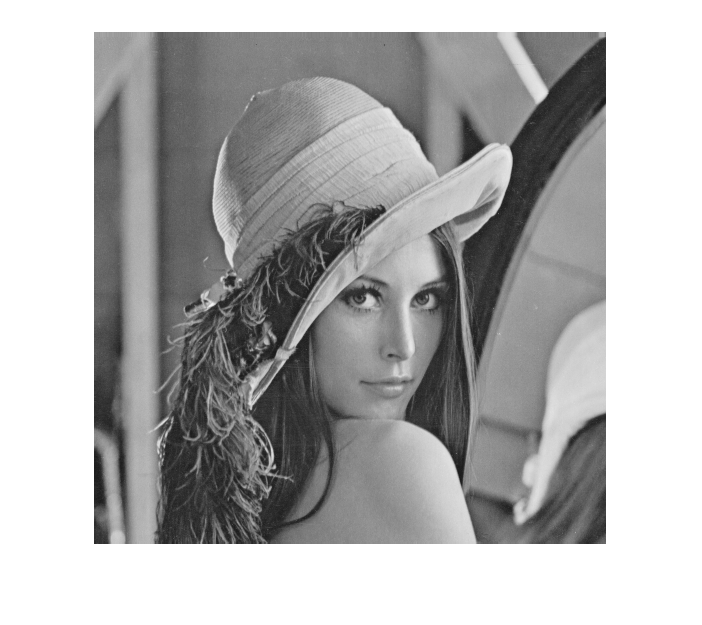

clear all;

I = imread("LENA512.BMP");
imshow(I);

Iascii = load("lena512.ascii");
S = imread("souris.bmp");


### Exercice 1 : Question 2

Calcul de l'entropie de l'image Lena

H = entropie(I)

H = 7.4455

### Exercice 1 : Question 3

%On soustrait 20 à tous les pixels
Imoins = I - 20;
%imshow(Imoins);
Hmoins = entropie(Imoins)

Hmoins = 7.4455


%On ajoute 20 à tous les pixels
Iplus = I + 20;
%imshow(Iplus);
Hplus = entropie(Iplus)

Hplus = 7.4455

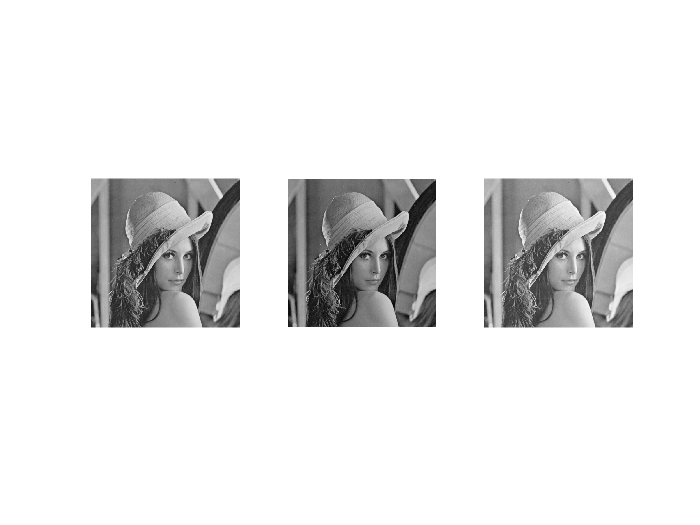


figure;
subplot(1, 3, 1)
imshow(I);
subplot(1, 3, 2)
imshow(Imoins);
subplot(1, 3, 3)
imshow(Iplus);

### Exercice 1: Question 4

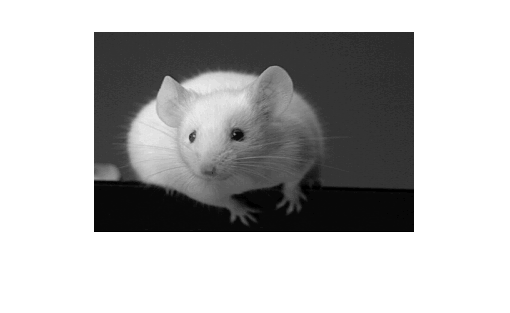

figure;
imshow(S);

HS = entropie(S)

HS = 5.5643

### Exercice 1 : Question 5

L'entropie de l'image 'souris' étant plus faible que celle de l'image 'lena', 5.5643 contre 7.4455, on pourra compresser l'image 'souris' plus formtement sans perte.

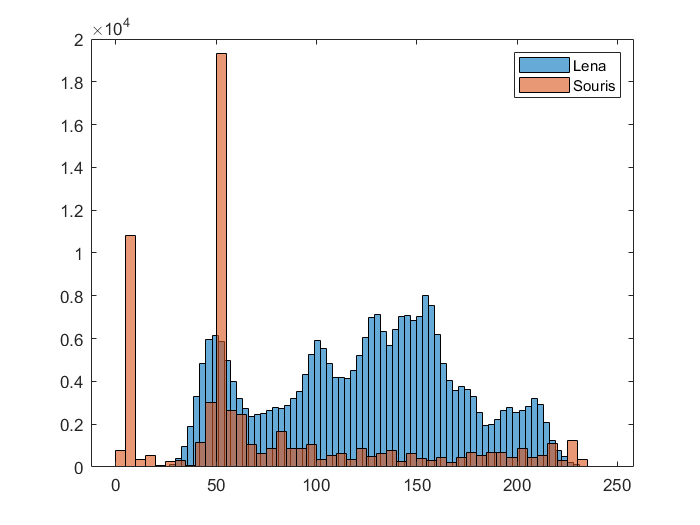

figure;
histogram(I);
hold on;
histogram(S);
legend("Lena", "Souris");

### Exercice 2 : Question 2

psnr = PSNR(S, S)

psnr = Inf

Sbruit = imnoise(S, "gaussian", 0.5);
psnrBruit = PSNR(S, Sbruit)

psnrBruit = 6.4673

### Exercice 3 : Question 2

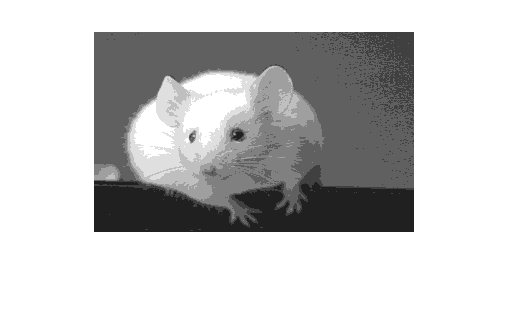

figure;
imshow(QSU(S, 8));

### Exercice 4

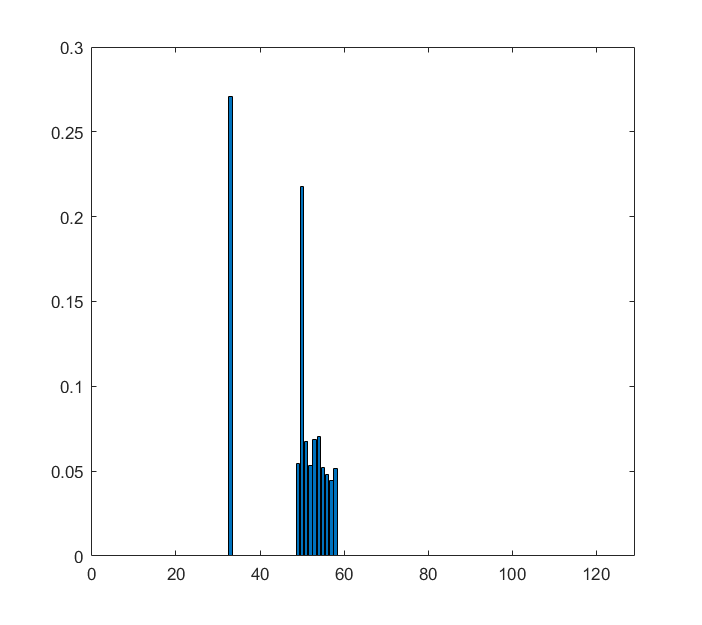

probs =          0         0         0         0         0         0         0         0         0         0    0.0005         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.2708         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0543    0.2177


lengths =     14    14    14    14    14    14    14    14    14    14     7    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14     2    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14     4     2


%255 codé par 2 ASCII, 5 ASCII et 5 ASCII => plus volumineux
[probs, lengths] = Huffman('lena512.ascii')

# Fonctions

### Exercice 1 : Question 1

Fonction de calcul de l'entropie

function H = entropie(I)

D = double(I);
K = 256;
compteur = zeros(1, K);

[l, c] = size(I);

%On compte le nombre d'apparition de chaque pixel
for i = 1:l
   for j = 1:c
      compteur(1, D(i,j)+1) = compteur(1, D(i,j)+1) + 1;
   end
end

H = 0;
%On calcule l'entropie
for i=1:K
    if(compteur(1, i) ~= 0)
        compteur(1, i) = compteur(1, i)/(l*c);
        H = H - compteur(1, i)*log2(compteur(1, i));
    end
end
end


### Exercice 2 : Question 1

function R = PSNR(I, J)

Id = double(I);
Jd = double(J);

[l, c] = size(I);
D = 0;

for i = 1:l
   for j = 1:c
      D = D + (Id(i,j) - Jd(i,j))^2;
   end
end

D = D/(c*l);
R = 10*log10(255*255/D);

end


### Exercice 3 : Question 3

function Q = QSU(I, nb_niveaux)

Q = double(I);
q = 255/nb_niveaux;
d = min(I(:));

[l, c] = size(I);
for i = 1:l
   for j = 1:c
      if Q(i,j) == 255
          Q(i,j) = nb_niveaux;
      else
          Q(i, j) = (floor((Q(i,j)-d)/q) + 1/2)*q+d;      
      end
   end
end

Q = uint8(Q);

end

### Exercice 4